clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
SavingPath = './GraphForPaper/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
step = 29

step = 29

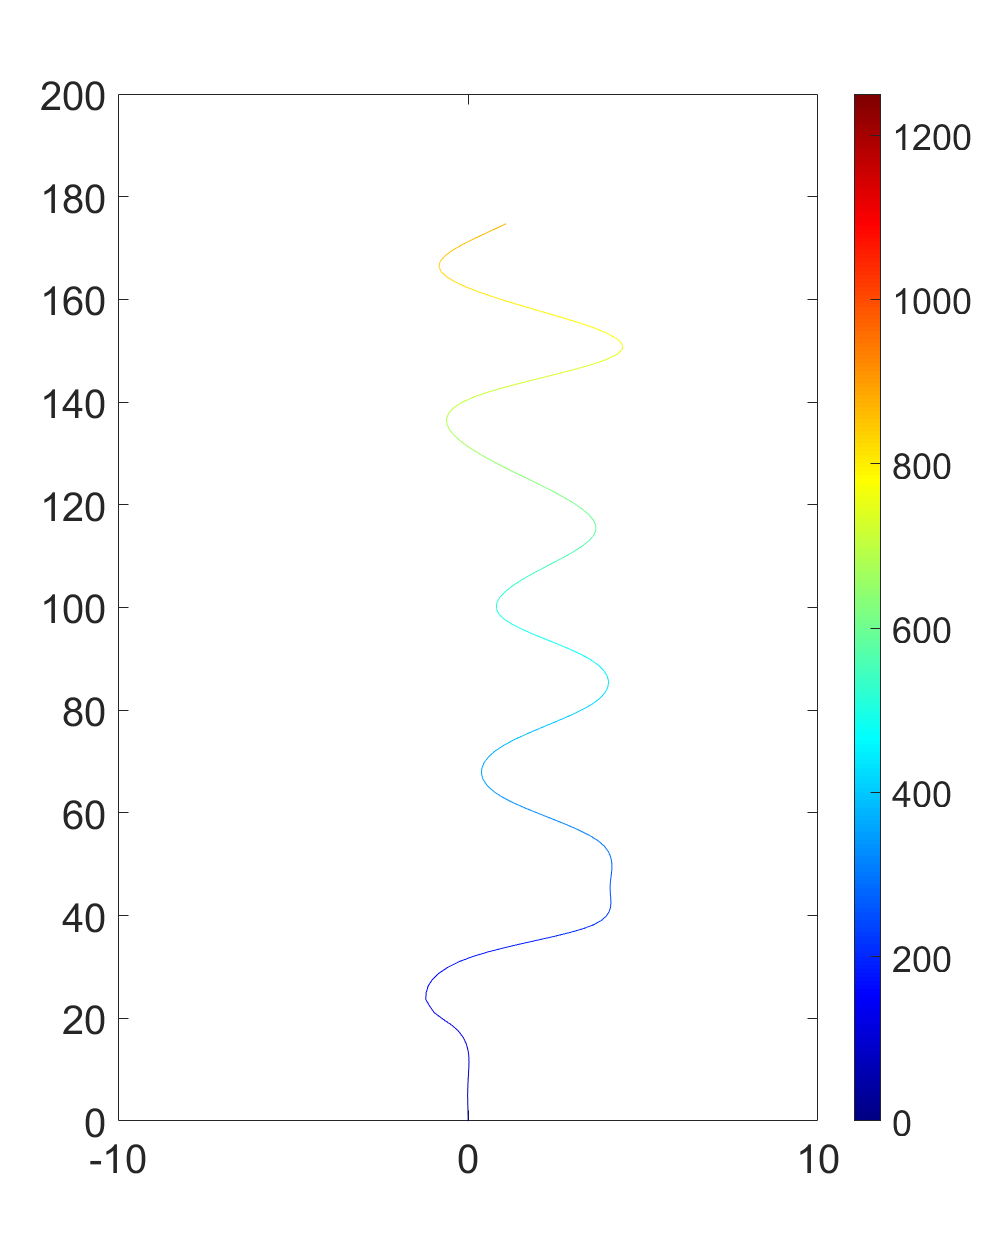

d = -1.2529

for i = step:step
    clf;
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        
        z = traj3D(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj3D = traj3D(1:top,:);
        
        
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = 0; d = Plane(3)
        x = traj3D(:,1); y = traj3D(:,2); z = traj3D(:,3); w = traj3D(:,6);
        T = [];
        xp = []; yp = [];
        for j = 1 : length(x)
            [px,py,pz]=projection(a,b,c,d,x(j),y(j),z(j));
            xp(j) = px;
            yp(j) = py;
        end
        xp = xp - xp(1);
        yp = yp - yp(1);
        for j = 1 : length(x)
            T(j) = sqrt(xp(j)^2 + yp(j)^2);
            if xp(j) < 0
                T(j) = -T(j);
            end
        end
        
        
%         slope = -a/b; AntiSlope = -1/slope;
%         LengthUnit = sqrt(1 + (1/AntiSlope)^2);
%         unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
%         yV = [0, -1];
%         theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
%         if -1/AntiSlope/LengthUnit < 0
%             theta = -theta
%         end
        %ax(i) = subplot(3,4,i);
        %plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        z(end) = nan;
    
        index = 21;
        T(1:index) = 0;
        addextra = 5;
        pfit = polyfit(z(1:index + addextra), T(1:index + addextra), 4);
        T(1:index + addextra) =polyval(pfit, z(1:index + addextra));
        T(1:index + addextra + 2) = smooth(z(1:index + addextra + 2),T(1:index + addextra + 2));
        
        
        
        
        patch(T,z,c,'FaceColor','none','EdgeColor','interp');
        caxis([0,1250]);
        colorbar;
        %axis equal;
        xlim([-10, 10]);
        ylim([0, 200]);
        box on;
%         a = get(gca,'XTickLabel');
%         set(gca,'XTickLabel',a,'FontName','Times','fontsize',12)
%         b = get(gca,'YTickLabel');
%         set(gca,'YTickLabel',b,'FontName','Times','fontsize',12)
        %ylim([-10, 10]);
        xticks([-10 0 10]);
        %view(theta, 0);
        
        ax = gca;
        ax.FontSize = 24; 
        set(gcf,'position',[0,0,800,1600]);
        set(gcf,'color','w');
        savefig([SavingPath,FileName{i},'SIDE.fig'])
    end
end

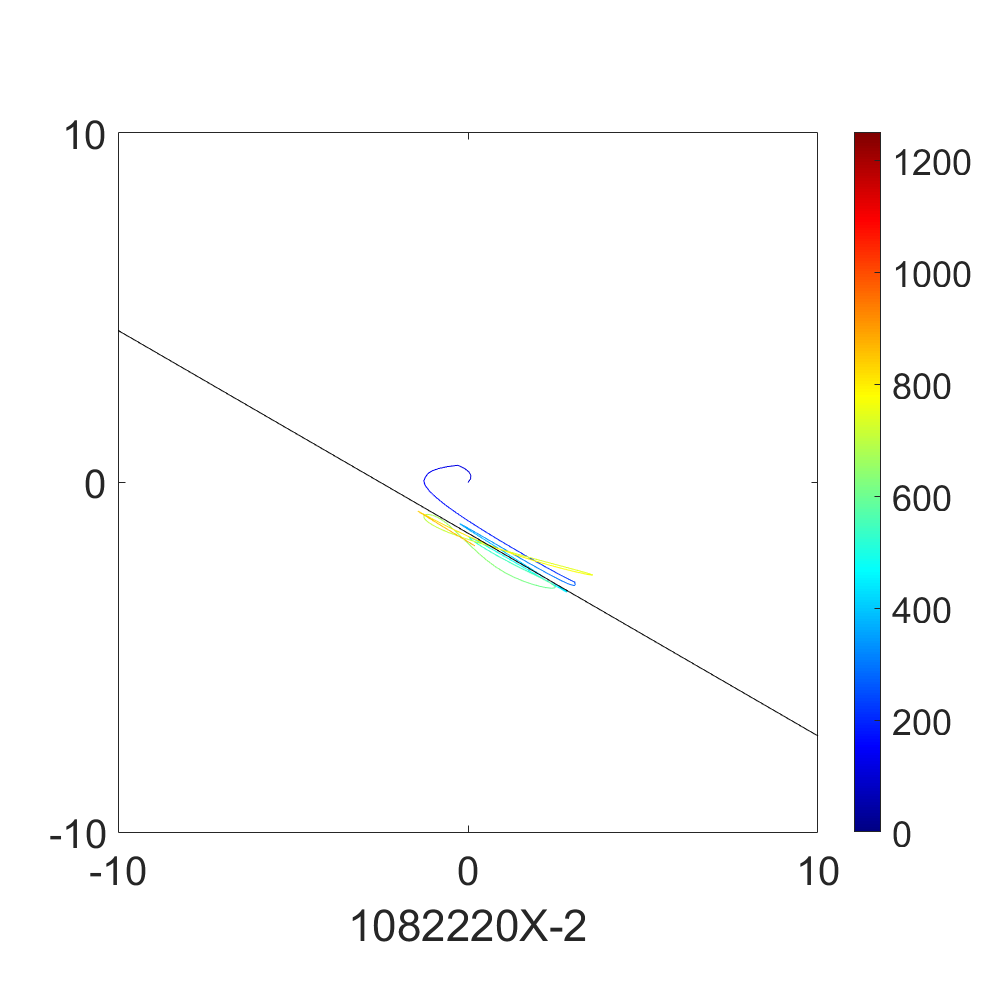

    
figure('visible','on');
for i = step:step
    clf;
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        
        z = traj(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj = traj(1:top,:);
        
        
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        %ax(i) = subplot(3,4,i);
        
        %plot(x,y);
        
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        y(end) = nan;
    
        x(1:index) = 0; y(1:index) = 0;
        pfit = polyfit(x(1:index + addextra), y(1:index + addextra), 6);
        y(1:index + addextra) =polyval(pfit, x(1:index + addextra));
        x(1:index + addextra + 5) = smooth(x(1:index + addextra +5));
        y(1:index +addextra +5) = smooth(y(1:index + addextra +5));
        patch(x,y,c,'FaceColor','none','EdgeColor','interp');
%         
        
        hold on;
        
    
        plot(xline,yline,'-k');
        
        %hold on;
        %quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        xlim([-10, 10]);
        ylim([-10, 10]);
        colorbar;
        %xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d); FileName{i}})
        xlabel(FileName{i});
        box on;
        caxis([0, 1250]);
        yticks([-10 0 10]);
        xticks([-10 0 10]);
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        ax = gca;
        ax.FontSize = 24; 
        save(path,'traj3D','Plane');
        set(gcf,'position',[0,0,800,800]);
        set(gcf,'color','w');
        savefig([SavingPath,FileName{i},'TOP.fig'])
    end
end

function [px,py,pz]=projection(a,b,c,d,x,y,z)
    % given an plane equation ax+by+cz=d, project points xyz onto the plane
    % return the coordinates of the new projected points
    % written by Neo Jing Ci, 11/7/18
    A=[1 0 0 -a; 0 1 0 -b; 0 0 1 -c; a b c 0];
    B=[x; y; z; d];
    X=A\B;
    px=X(1);
    py=X(2);
    pz=X(3);
end